## Intro

This scrip try to  using data input to draw residual changing figure.

## Input

Total_experiment_number=100;
step_length=1/50;
sample_length=1/100;

load residual history

data_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\P.S.G.D\data\第三轮梯度下降';

Total_residual_history=[];
Total_parameter_history=[];

fileFolder=fullfile(data_location);
dirOutput=dir(fullfile(fileFolder,'*.mat'));
fileNames={dirOutput.name};
n_data_file=length(fileNames);
for i=1:n_data_file
    load([data_location,'\',strcat(fileNames{i})]);
    for j=1:length(residual_history)
        Total_residual_history=[Total_residual_history;residual_history(j)];
        Total_parameter_history=[Total_parameter_history;parmeter_history(j,:)];
    end
end

## Plotting residual history

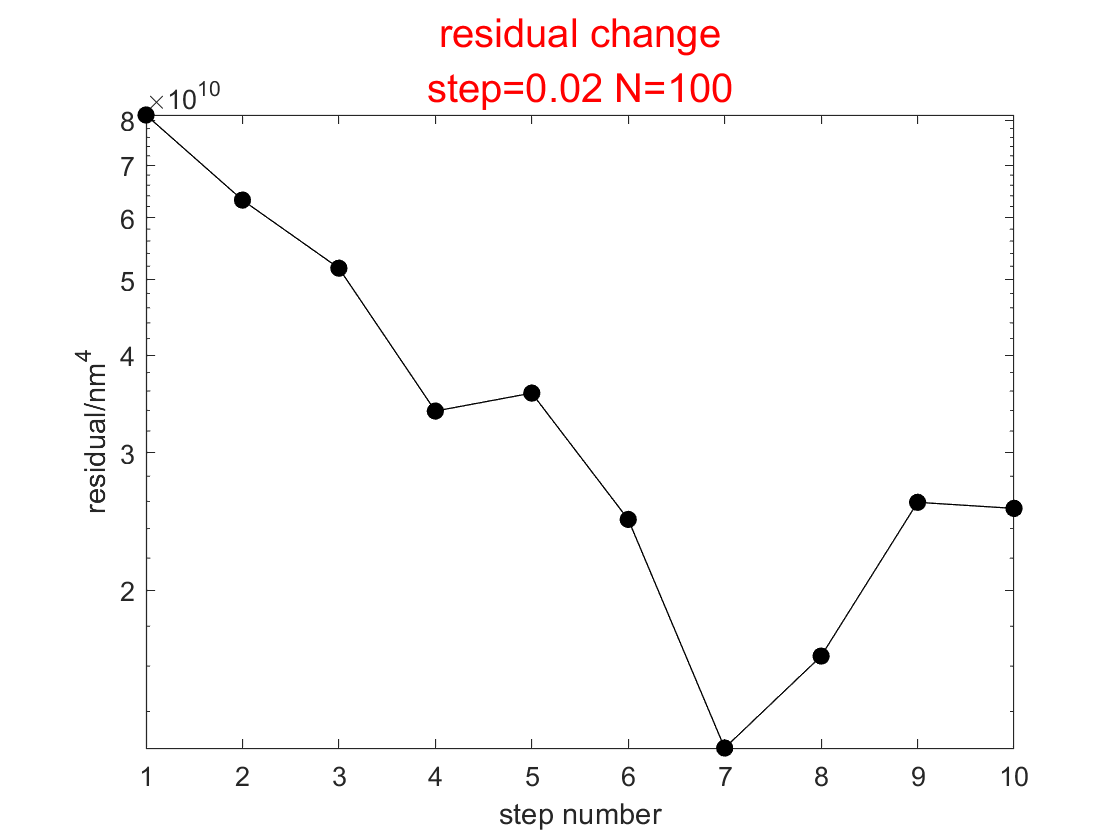

figure
plot((Total_residual_history)*1e36,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^4')
set(gca,'yscale','log');
title({'residual change',['step=',num2str(step_length),' N=',num2str(Total_experiment_number)]},'Color','r','FontSize',15)

## Plotting parameter history

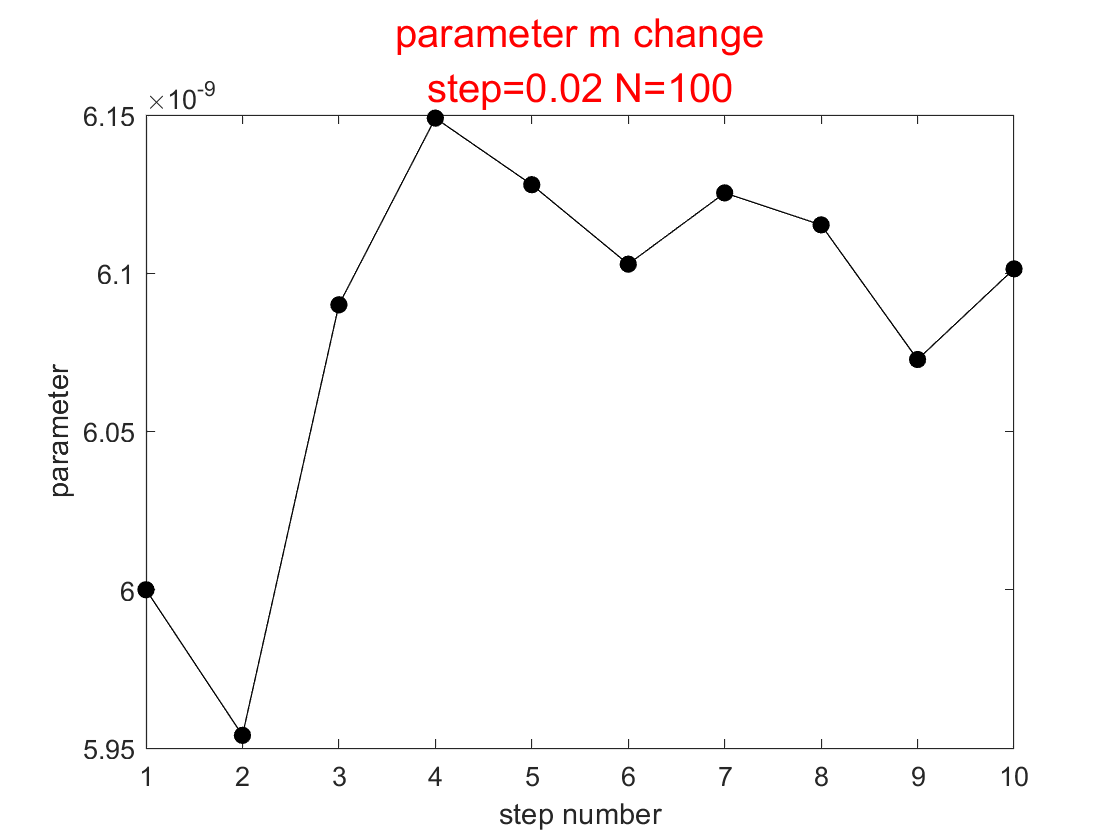

parameter_name='m';
figure
plot((Total_parameter_history(:,1)),'k-o','MarkerFaceColor','k','displayname','')
xlabel('step number')
ylabel('parameter')
title({['parameter ',parameter_name,' change'],['step=',num2str(step_length),' N=',num2str(Total_experiment_number)]},'Color','r','FontSize',15)